# 各種目の予測モデル

得点割合を説明するレーティング差を予測勝率を対応させるモデルを図示する．

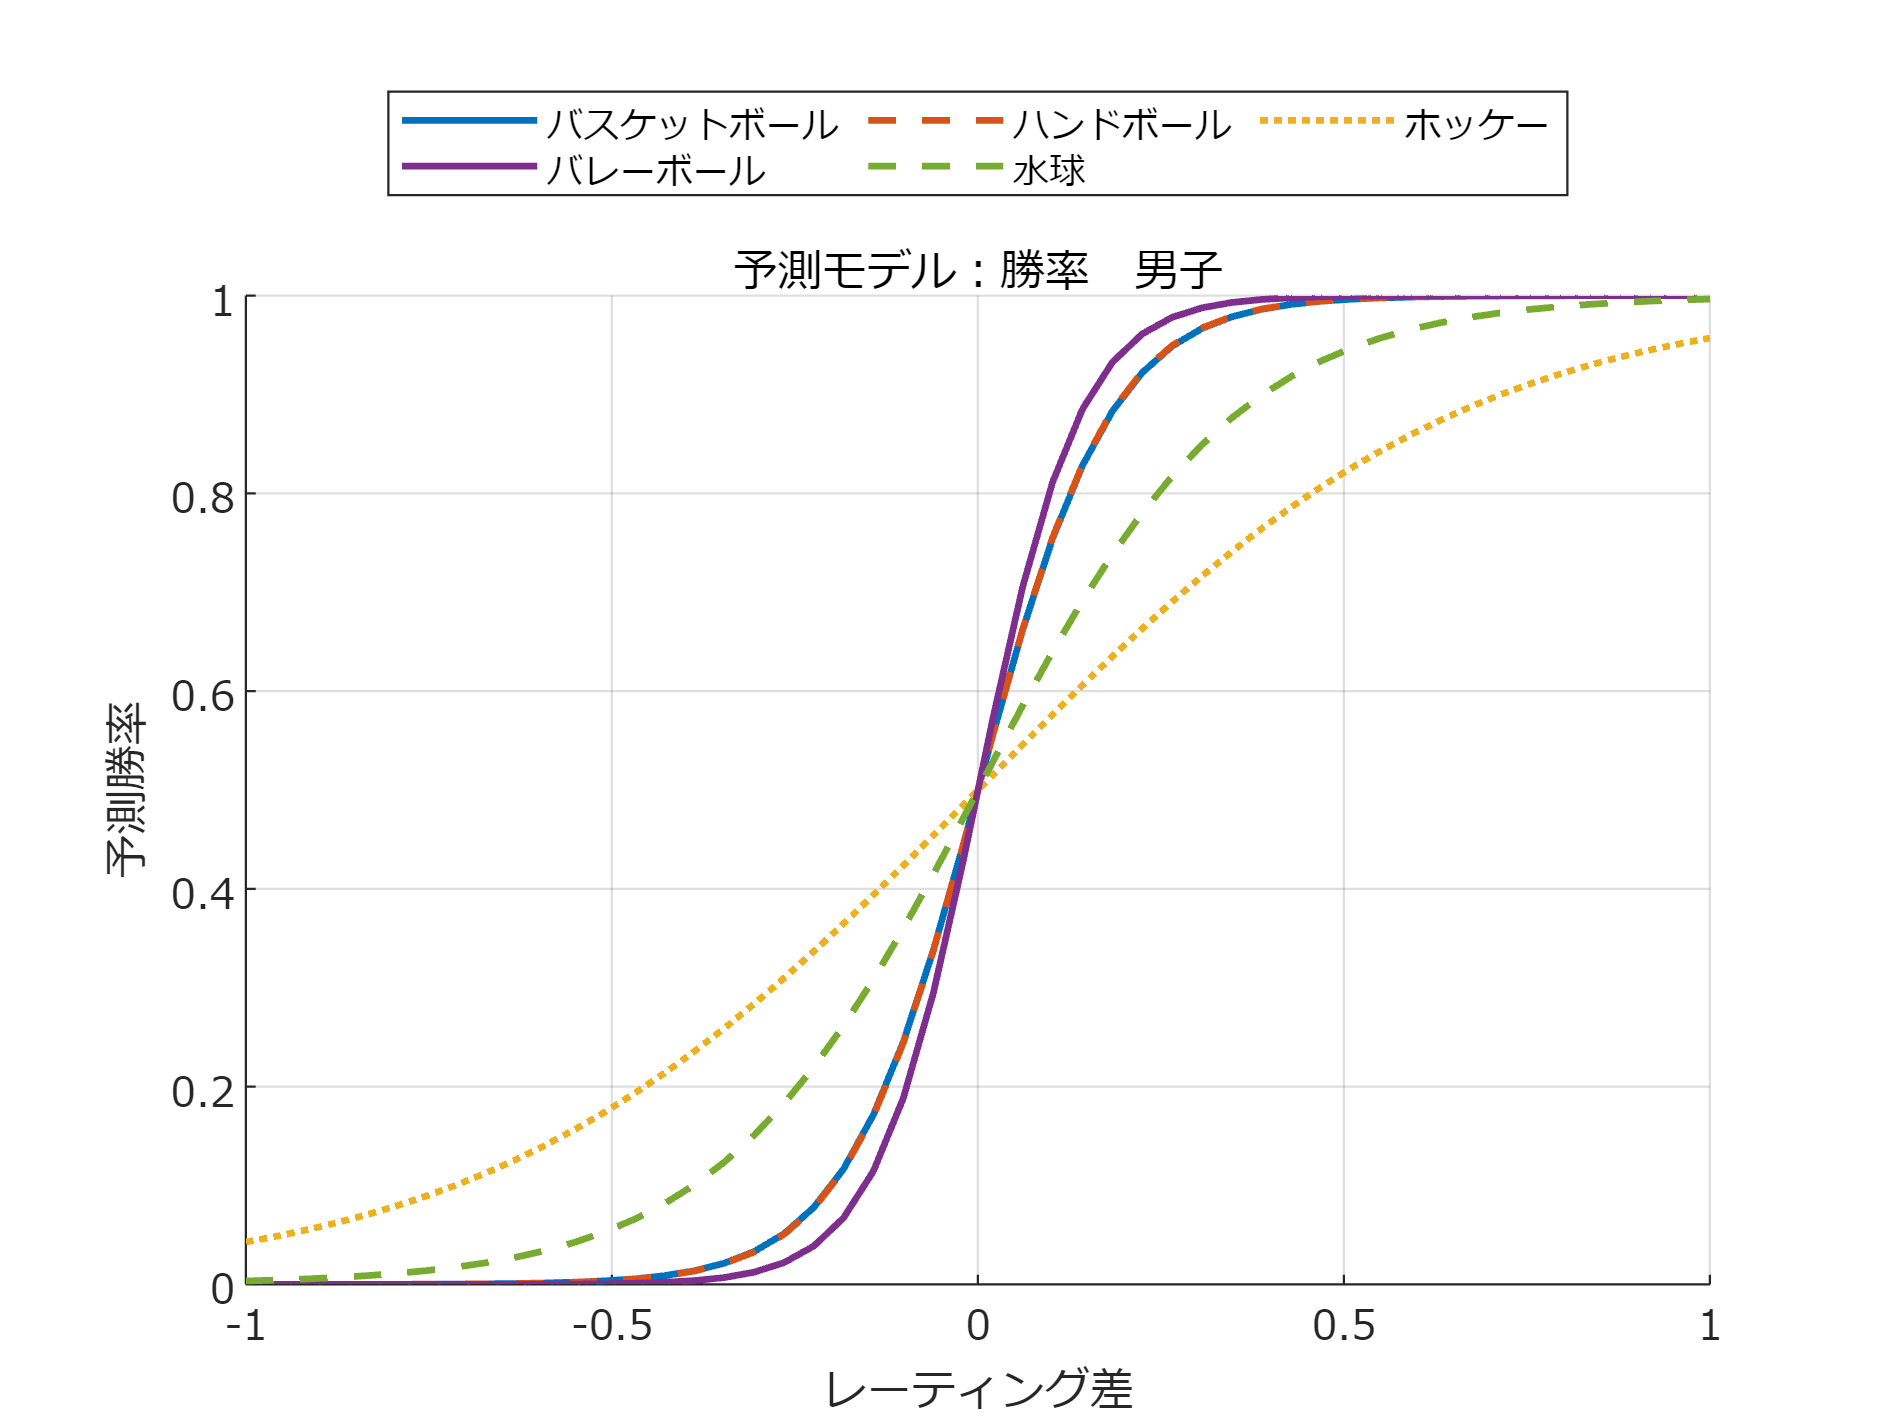

clear
clc
close all

figure;hold on;grid on;
set(gca,'fontname','メイリオ');
bins=linspace(-1,1,50);
load("./basketball/rating_M_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'LineWidth',1.5);

load("./handball/rating_M_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'--','LineWidth',1.5);

load("./hockey/rating_M_.mat","mdl");
plotY=glmval(mdl.win,bins,'logit')-glmval(mdl.lose,bins,'logit');
plotY=plotY/2+0.5;
plot(bins,plotY,':','LineWidth',1.5);

load("./volleyball/rating_M_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'LineWidth',1.5);

load("./waterpolo/rating_M_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'--','LineWidth',1.5);

xlabel('レーティング差');
ylabel('予測勝率');
title('予測モデル：勝率　男子')
legend({'バスケットボール', ...
    'ハンドボール', ...
    'ホッケー', ...
    'バレーボール', ...
    '水球', ...
    },'Location','northoutside','Orientation','horizontal', ...
    'NumColumns',3);
exportgraphics(gcf,'fig_predictionModel_M.pdf');

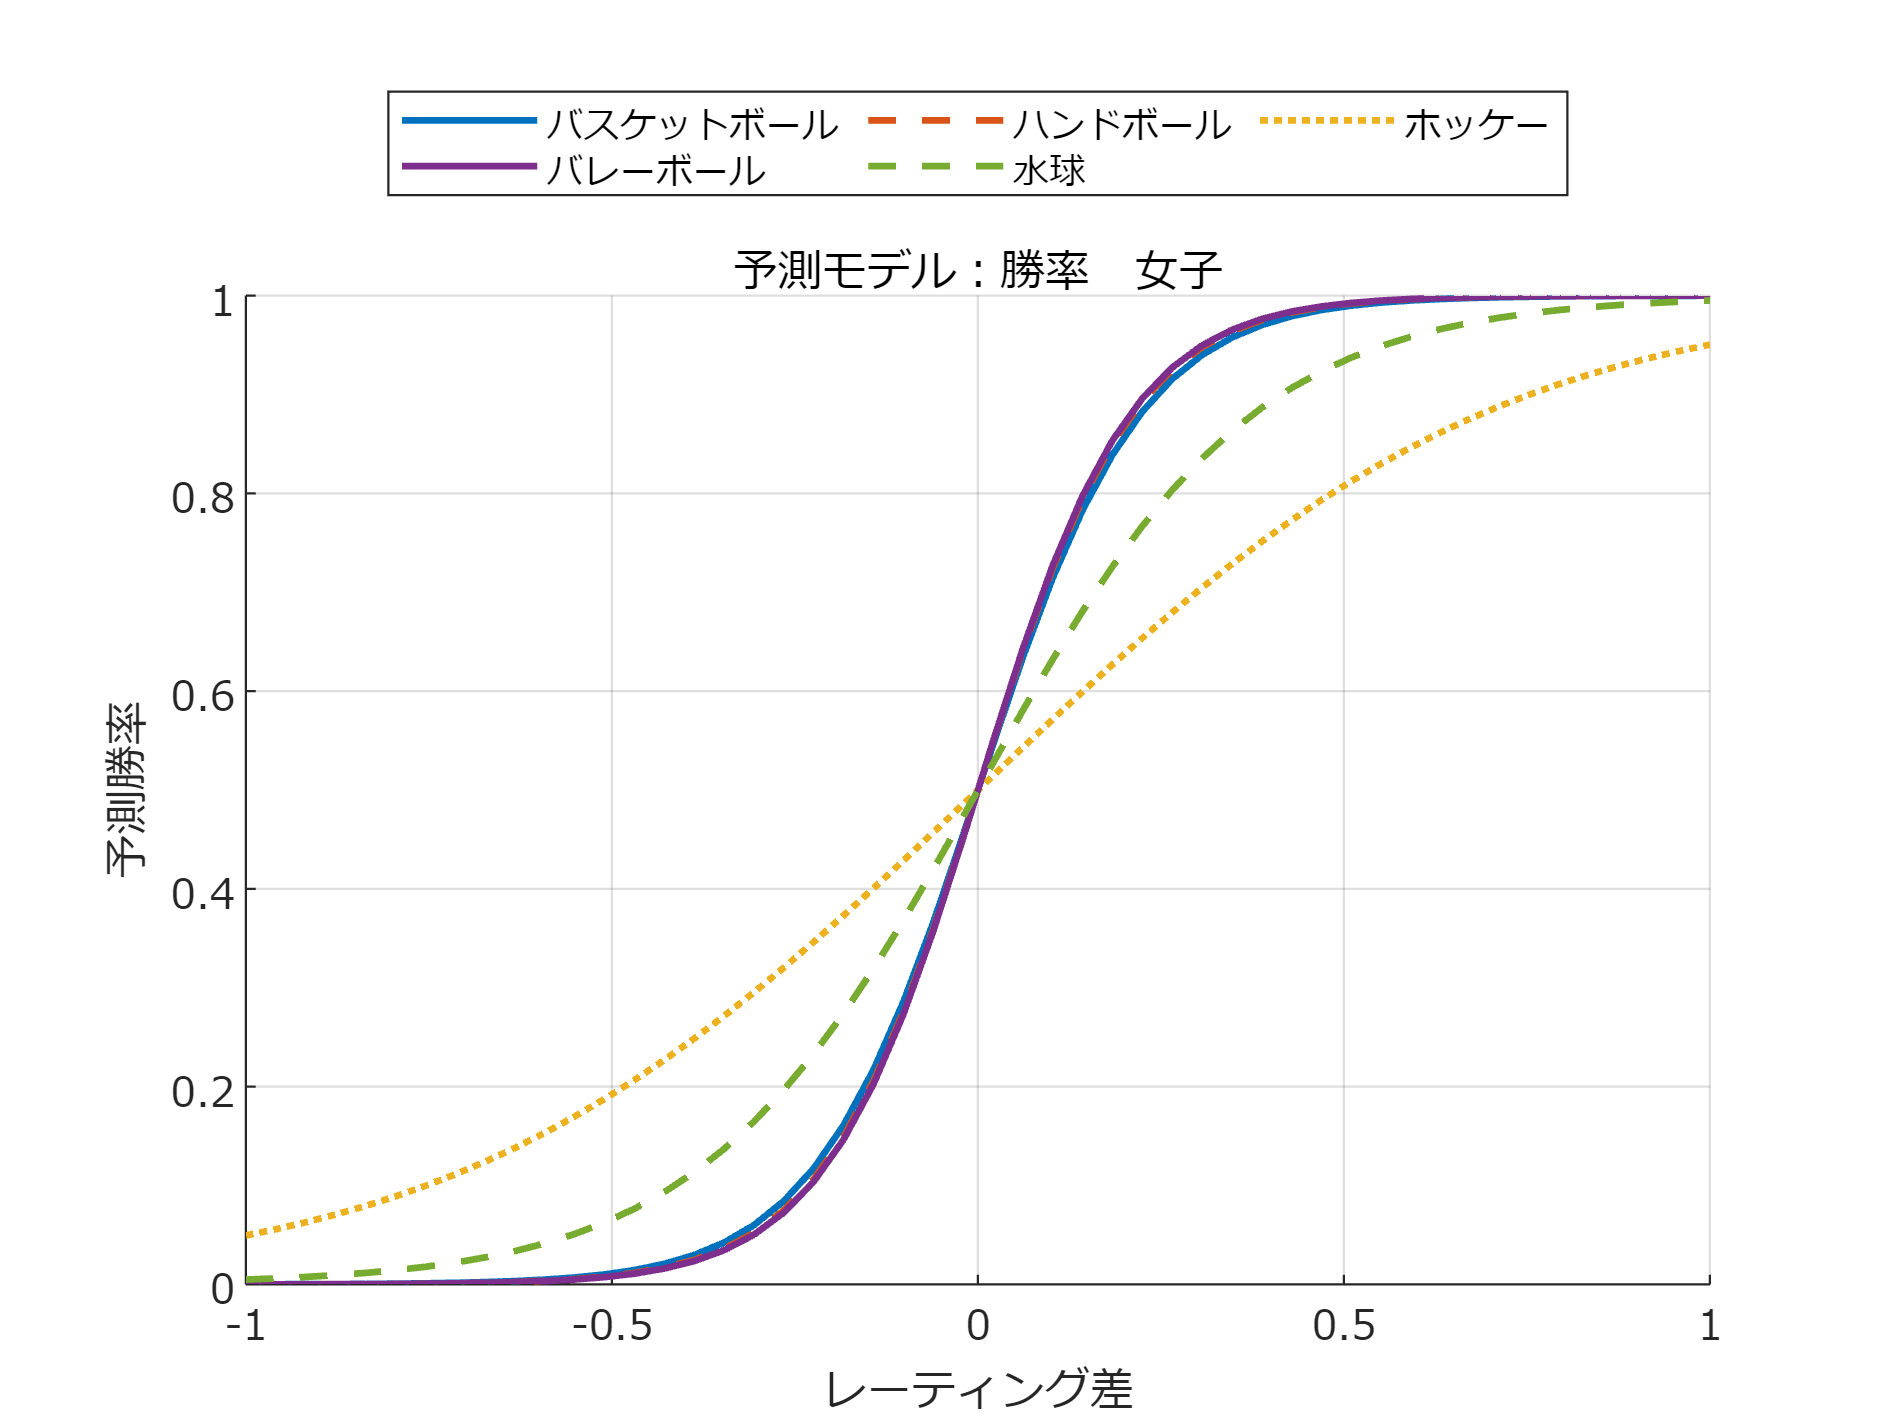

figure;hold on;grid on;
set(gca,'fontname','メイリオ');
bins=linspace(-1,1,50);
load("./basketball/rating_W_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'LineWidth',1.5);

load("./handball/rating_W_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'--','LineWidth',1.5);

load("./hockey/rating_W_.mat","mdl");
plotY=glmval(mdl.win,bins,'logit')-glmval(mdl.lose,bins,'logit');
plotY=plotY/2+0.5;
plot(bins,plotY,':','LineWidth',1.5);

load("./volleyball/rating_W_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'LineWidth',1.5);

load("./waterpolo/rating_W_.mat","mdl");
plot(bins,glmval(mdl,bins,'logit'),'--','LineWidth',1.5);

xlabel('レーティング差');
ylabel('予測勝率');
title('予測モデル：勝率　女子')
legend({'バスケットボール', ...
    'ハンドボール', ...
    'ホッケー', ...
    'バレーボール', ...
    '水球', ...
    },'Location','northoutside','Orientation','horizontal', ...
    'NumColumns',3);
exportgraphics(gcf,'fig_predictionModel_W.pdf');